clear
% 52
% Calculation of body volume
% V=int int f(x,y)*dx*dy

syms x y z;
% y=1+x^2
% z=3*x
% y=5
% z=0

V=int(int(3*x,y,1+x^2,5),x,0,2)

$$V = 12$$

% 12

% 53
% Calculation of body volume
% V=int int f(x,y)*dx*dy

% z=1-x^2-y^2
% y=x
% y=x*sqrt(3)
% z=0

syms rho theta
x=rho*cos(theta)

$$x = \rho \,\cos\left(\theta \right)$$

y=rho*sin(theta)

$$y = \rho \,\sin\left(\theta \right)$$

z=1-x^2-y^2

$$z = -\rho^{2}\,{\cos\left(\theta \right)}^{2}-\rho^{2}\,{\sin\left(\theta \right)}^{2}+1$$

z=simplify(z)

$$z = 1-\rho^{2}$$

% tan(theta1)=1 => theta1=pi/4
% tan(theta2)=sqrt(3) => theta2=pi/3
V=int(int(z*rho,rho,0,1),theta,pi/4,pi/3)

$$V = \frac{\pi }{48}$$

% pi/48

% 54
% x^2+y^2=a^2
% x^2+z^2=a^2

syms x y a;
V=8*int(int(sqrt(a^2-x^2),y,0,sqrt(a^2-x^2)),x,0,a)

$$V = \frac{16\,a^{3}}{3}$$

% (16*a^3)/3

% 55
% x^2+y^2=8
% x=0,y=0,z=0,x+y+z=4

syms x y;
slv=solve(x^2+y^2==8,x+y==4)

slv = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]



eq1=x^2+y^2-8

$$eq1 = x^{2}+y^{2}-8$$

eq2=x+y-4

$$eq2 = x+y-4$$

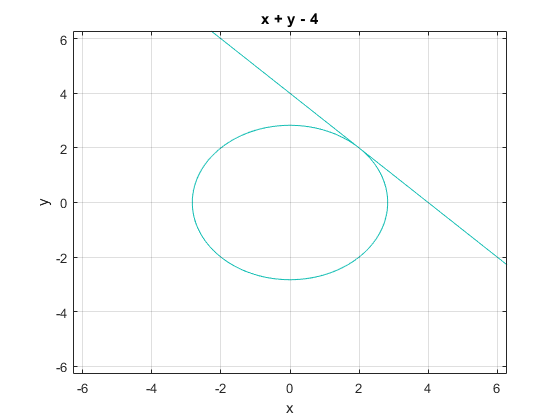


ezplot(eq1)
hold on
ezplot(eq2)
hold off
grid on


V=int(int(4-x-y,y,0,sqrt(8-x^2)),x,0,sqrt(8))

$$V = 8\,\pi -\frac{32\,\sqrt{2}}{3}$$

% 8*pi - (32*2^(1/2))/3

% 56
% x=2*y^2
% x+2*y+z=4
% y=0
% z=0

eq1=x-2*y^2

$$eq1 = x-2\,y^{2}$$

eq2=x+2*y-4

$$eq2 = x+2\,y-4$$

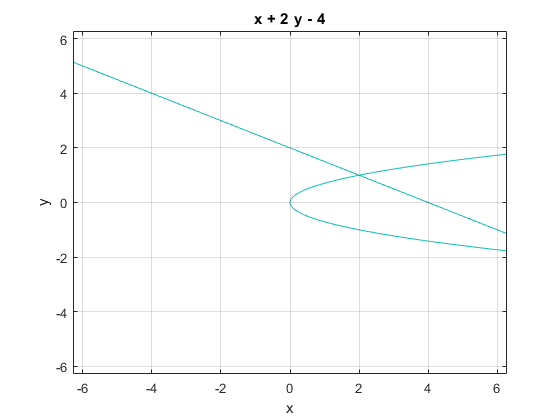

ezplot(eq1)
hold on
ezplot(eq2)
hold off
grid on

slv=solve(eq1==0,eq2==0)

slv = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


pp=[slv.x,slv.y]

$$pp = \left(\begin{array}{cc} 2 & 1\\ 8 & -2 \end{array}\right)$$


V=int(int(4-x-2*y,x,2*y^2,4-2*y),y,0,1)

$$V = \frac{17}{5}$$

% 17/5

% 57
% x^2+4*y^2+z=1
% z=0
syms x y;

eq1=x^2+4*y^2-1

$$eq1 = x^{2}+4\,y^{2}-1$$

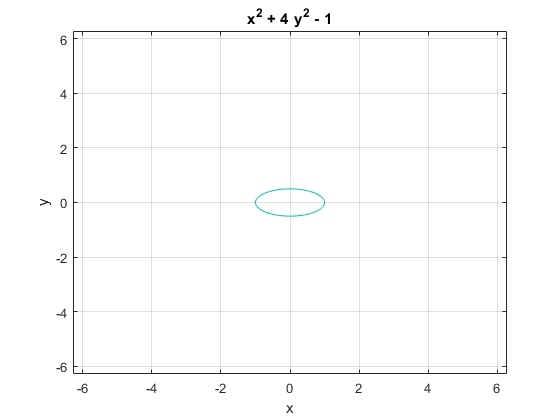

ezplot(eq1)
grid

V=2*int(int(1-x^2-4*y^2,y,sqrt(1-x^2),0),x,-1,1)

$$V = \frac{\pi }{4}$$

% pi/4

% 58
% z=x^2+y^2
% y=x^2
% y=1
% z=0

syms x y;
V=int(int(x^2+y^2,y,x^2,1),x,-1,1)

$$V = \frac{88}{105}$$

% 88/105

% 59
% z=4-x^2
% 2*x+y=4
% x=0
% y=0
% z=0

syms x y;
y1=0

y1 =      0


y2=4-2*x

$$y2 = 4-2\,x$$

V=int(int(4-x^2,y,0,4-2*x),x,0,2)

$$V = \frac{40}{3}$$

% 40/3

% 60
% z^2=x*y
% x=0
% x=1
% y=0
% y=4
% z=0

syms x y;
V=int(int(sqrt(x*y),y,0,4),x,0,1)

$$V = \frac{32}{9}$$

% 32/9

% 61
% z=5*x
% x^2+y^2=9
% z=0

syms x y;
V=int(int(5*x,x,0,sqrt(9-y^2)),y,-3,3)

$$V = 90$$

% 90

% 62
% x+y+z=6
% 3*x+2*y=12
% 3*x+y=6
% y=0
% z=0

syms x y;
y1=6-3/2*x

$$y1 = 6-\frac{3\,x}{2}$$

y2=6-3*x

$$y2 = 6-3\,x$$

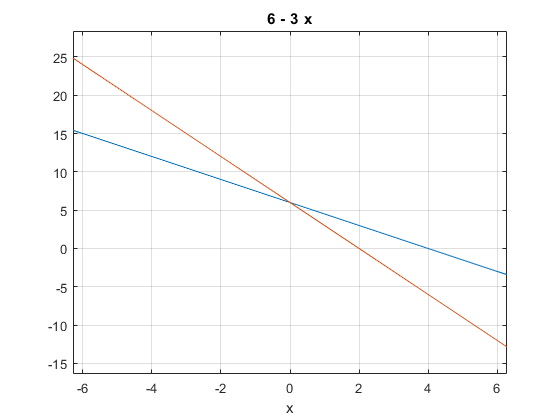

ezplot(y1)
hold on
ezplot(y2)
hold off
grid on


x1=(12-2*y)/3

$$x1 = 4-\frac{2\,y}{3}$$

x2=(6-y)/3

$$x2 = 2-\frac{y}{3}$$


V=int(int(6-x-y,x,x2,x1),y,0,6)

$$V = 12$$

% 12

% 63
% z=x+y+1
% y^2=x
% x=1
% y=0
% z=0

syms x y;
V=int(int(x+y+1,x,y^2,1),y,0,1)

$$V = \frac{79}{60}$$

% 79/60

% 64
% z=0
% z=x*y
% x^2+y^2=4

syms x y;
V=2*int(int(x*y,y,0,sqrt(4-x^2)),x,0,2)

$$V = 4$$

% 4

% 65
% x^2/a^2+y^2/b^2=1
% y=0
% z=x/2
% z=x

syms x y a b;
y1=b*sqrt(1-x^2/a^2)

$$y1 = b\,\sqrt{1-\frac{x^{2}}{a^{2}}}$$


V1=int(int(x/2,y,0,y1),x,0,a)

$$V1 = \frac{a^{2}\,b}{6}$$

V2=int(int(x,y,0,y1),x,0,a)

$$V2 = \frac{a^{2}\,b}{3}$$


V=2*(V2-V1)

$$V = \frac{a^{2}\,b}{3}$$

% (a^2*b)/3
